# Acoustics-Based Dataset

In this example, you will inspect dataset from an air compressor using acoustic measurements. 

## Data **Preparation**

Download and unzip the air compressor data set [1]. This data set consists of recordings from air compressors in a healthy state or one of seven faulty states.

rng default
dataFolder = "L:\Work_CurrentRelease\25aWork\ESWeek_T7\";
dataset = fullfile(dataFolder,"AirCompressorDatasetSmall");

Create an [`audioDatastore`](docid:audio_ref#mw_6315b106-9a7b-4a11-a7c6-322c073e343a) object to manage the data and split it into training and validation sets.

ads = audioDatastore(dataset, ...
    IncludeSubfolders=true, ...
    OutputDataType="single");

You can reduce the training data set used in this example to speed up the runtime at the cost of performance. In general, reducing the data set is a good practice for development and debugging.

The data labels are encoded in their containing folder name. To split the data into train and test sets, use [`folders2labels`](docid:signal_ref#mw_e777c085-9de7-4fe3-a089-1f9c459e27f1) and [`splitlabels`](docid:signal_ref#mw_c3ecb099-70f0-4ea2-923c-d66fdc4beadb).

lbls = folders2labels(ads.Files);
idxs = splitlabels(lbls,0.9);

adsTrain = subset(ads,idxs{1});
labelsTrain = lbls(idxs{1});
adsValidation = subset(ads,idxs{2});
labelsValidation = lbls(idxs{2});

Call [`countlabels`](docid:signal_ref#mw_e2562c05-2e36-4638-b49c-0fdc625631ab) to inspect the distribution of labels in the train and validation sets.

countlabels(labelsTrain)

ans = 8×3 table
      Label      Count    Percent
    _________    _____    _______

    Bearing       45       12.5  
    Flywheel      45       12.5  
    Healthy       45       12.5  
    LIV           45       12.5  
    LOV           45       12.5  
    NRV           45       12.5  
    Piston        45       12.5  
    Riderbelt     45       12.5  


countlabels(labelsValidation)

ans = 8×3 table
      Label      Count    Percent
    _________    _____    _______

    Bearing        5       12.5  
    Flywheel       5       12.5  
    Healthy        5       12.5  
    LIV            5       12.5  
    LOV            5       12.5  
    NRV            5       12.5  
    Piston         5       12.5  
    Riderbelt      5       12.5  


The data consists of time-series recordings of acoustics from faulty or healthy air compressors. As such, there are strong relationships between samples in time. Listen to a recording and plot the waveform.

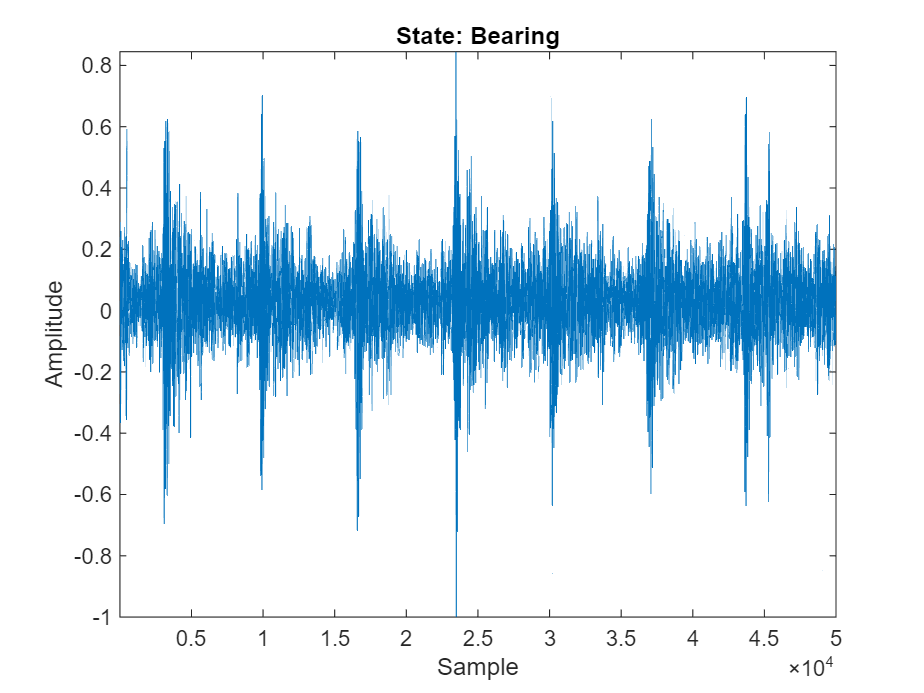

[sampleData,sampleDataInfo] = read(adsTrain);
fs = sampleDataInfo.SampleRate;

soundsc(gather(sampleData),fs)
plot(sampleData)
xlabel("Sample")
ylabel("Amplitude")
title("State: " + string(labelsTrain(1)))
axis tight

Because the samples are related in time, you can use a recurrent neural network (RNN) to model the data. A long short-term memory (LSTM) network is a popular choice of RNN because it is designed to avoid vanishing and exploding gradients. Before you can train the network, it's important to prepare the data adequately. Often, it is best to transform or extract features from 1-dimensional signal data in order to provide a richer set of features for the model to learn from.

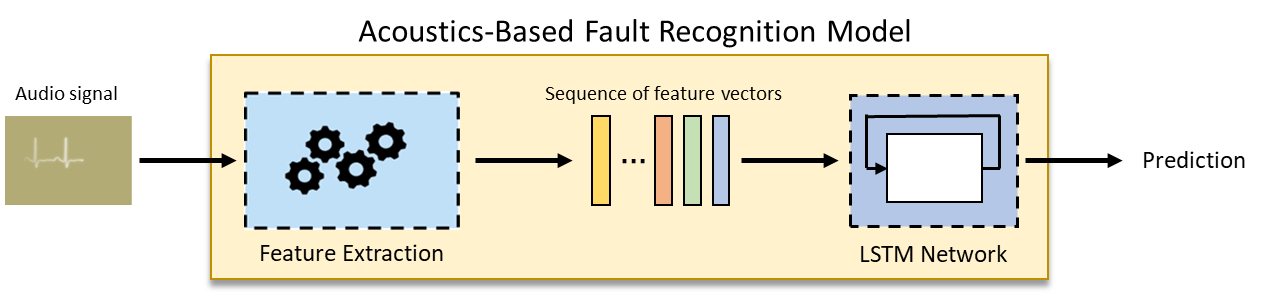

## Feature Engineering

The next step is to extract a set of acoustic features used as inputs to the network. Audio Toolbox™ enables you to extract spectral descriptors that are commonly used as inputs in machine learning tasks. You can extract the features using individual functions, or you can use [`audioFeatureExtractor`](docid:audio_ref#mw_b56cd7dc-af31-4da4-a43e-b13debc30322) to simplify the workflow and do it all at once. After feature extraction, orient time along rows which is the expected format for sequences in Deep Learning Toolbox™.

windowLength = 512;
overlapLength = 0;

afe = audioFeatureExtractor(SampleRate=fs, ...
    Window=hamming(windowLength,"periodic"),...
    OverlapLength=overlapLength,...
    spectralCentroid=true, ...
    spectralCrest=true, ...
    spectralDecrease=true, ...
    spectralEntropy=true, ...
    spectralFlatness=true, ...
    spectralFlux=false, ...
    spectralKurtosis=true, ...
    spectralRolloffPoint=true, ...
    spectralSkewness=true, ...
    spectralSlope=true, ...
    spectralSpread=true);

tic
trainFeatures = extract(afe,adsTrain);
disp("Feature extraction of train set took " + toc + " seconds.");

Feature extraction of train set took 5.0789 seconds.


### Data Augmentation

The training set contains a relatively small number of acoustic recordings for training a deep learning model. A popular method to enlarge the data set is to use mixup. In mixup, you augment your dataset by mixing the features and labels from two different class instances. Mixup was reformulated by [2] as labels drawn from a probability distribution instead of mixed labels. The supporting function, `mixup`, takes the training features, associated labels, and the number of mixes per observation and then outputs the mixes and associated labels.

numMixesPerInstance = 2;
tic
[augData,augLabels] = mixup(trainFeatures,labelsTrain,numMixesPerInstance);

trainLabels = cat(1,labelsTrain,augLabels);
trainFeatures = cat(1,trainFeatures,augData);
disp("Feature augmentation of train set took " + toc + " seconds.");

Feature augmentation of train set took 0.14323 seconds.


### Generate Validation Features

Repeat the feature extraction for the validation features.

tic
featuresValidation = extract(afe,adsValidation);
disp("Feature extraction of validation set took " + toc + " seconds.");

Feature extraction of validation set took 0.40547 seconds.


## Train Model

Next, you define and train a network. The pretrained model is also placed in the current folder when you open this example. To skip training the network, simply continue to the next section. 

### Define Network

An LSTM layer learns long-term dependencies between time steps of time series or sequence data. The first `lstmLayer` outputs sequence data. Then a dropout layer is used to reduce overfitting. The second `lstmLayer` outputs the last step of the time sequence.

numHiddenUnits = 100;
dropProb = 0.2;
layers = [ ...
    sequenceInputLayer(afe.FeatureVectorLength,Normalization="zscore")
    lstmLayer(numHiddenUnits,OutputMode="sequence")
    dropoutLayer(dropProb)
    lstmLayer(numHiddenUnits,OutputMode="last")
    fullyConnectedLayer(numel(unique(labelsTrain)))
    softmaxLayer];

### Define Network Hyperparameters

To define hyperparameters for the network, use `trainingOptions`.

miniBatchSize = 128;
validationFrequency = floor(numel(trainFeatures)/miniBatchSize);
options = trainingOptions("adam", ...
    Metric="accuracy", ...
    MiniBatchSize=miniBatchSize, ...
    MaxEpochs=100, ...
    Plots="training-progress", ...
    Verbose=false, ...
    Shuffle="every-epoch", ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropPeriod=30, ...
    LearnRateDropFactor=0.1, ...
    ValidationData={featuresValidation,labelsValidation}, ...
    ValidationFrequency=validationFrequency, ...
    ValidationPatience=10, ...
    OutputNetwork="best-validation-loss");

### Train Network

To train the network, use `trainnet`.

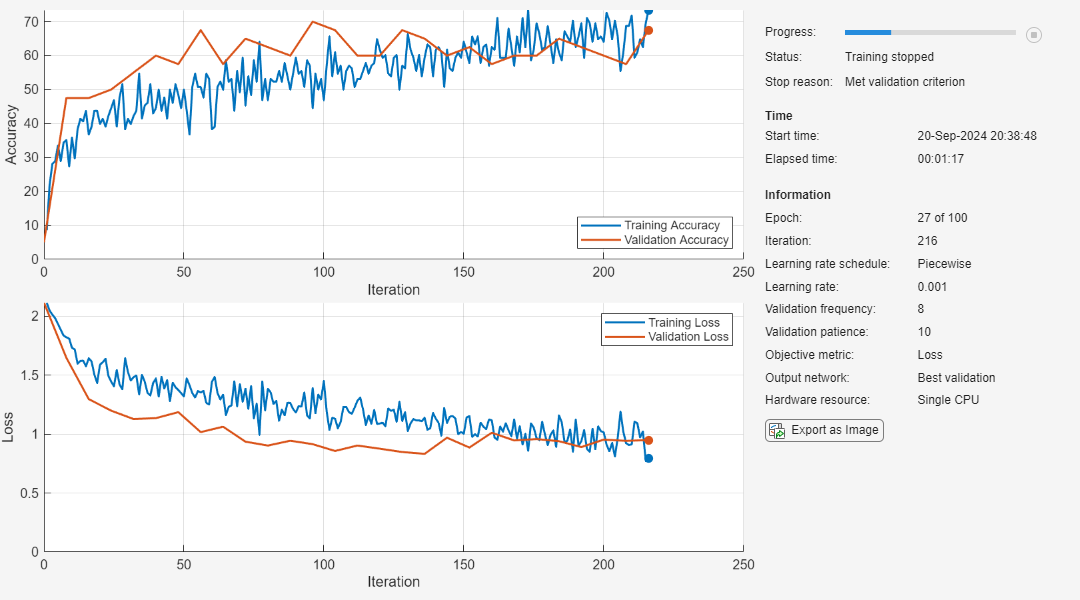

airCompNet = trainnet(trainFeatures,trainLabels,layers,"crossentropy",options);

### Evaluate Network

View the confusion chart for the validation data.

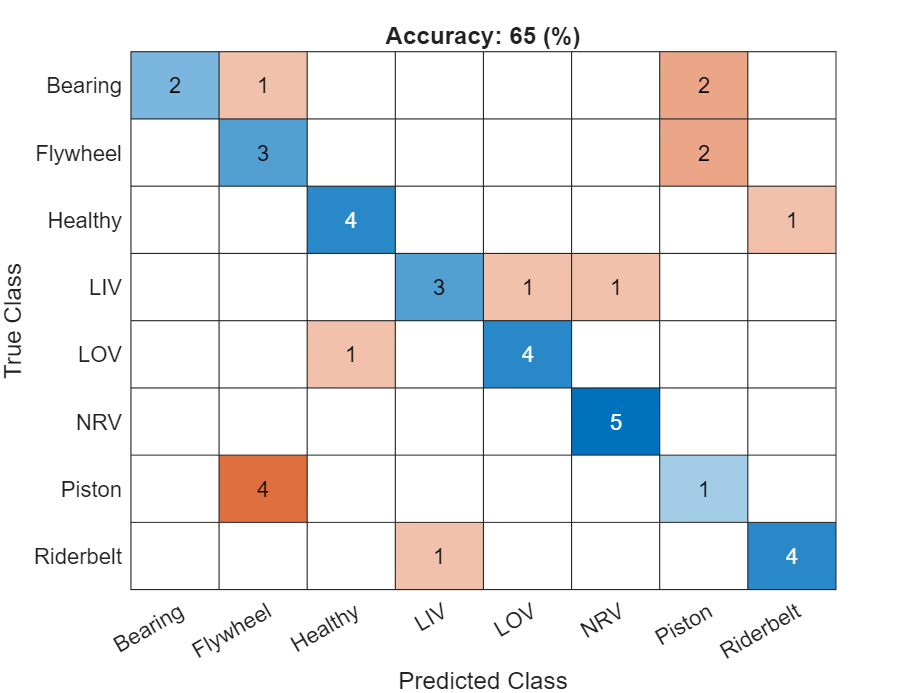

validationResults = minibatchpredict(airCompNet,featuresValidation);
uniqueLabels = unique(labelsTrain);
validationResults = scores2label(validationResults,uniqueLabels,2);
confusionchart(labelsValidation,validationResults, ...
    Title="Accuracy: " + mean(validationResults == labelsValidation)*100 + " (%)");

## Model Streaming Detection

#### Create Functions to Process Data in a Streaming Loop

Once you have a trained network with satisfactory performance, you can apply the network to test data in a streaming fashion. 

There are many additional considerations to take into account to make the system work in a real-world embedded system. 

For example,

- The rate or interval at which classification can be performed with accurate results

- The size of the network in terms of generated code (program memory) and weights (data memory)

- The efficiency of the network in terms of computation speed

In MATLAB, you can mimic how the network is deployed and used in hardware on a real embedded system and begin to answer these important questions. 

#### Create MATLAB Function Compatible with C/C++ Code Generation

Once you train your deep learning model, you will deploy it to an embedded target. That means you also need to deploy the code used to perform the feature extraction. Use the `generateMATLABFunction` method of `audioFeatureExtractor` to generate a MATLAB function compatible with C/C++ code generation. Specify `IsStreaming` as `true` so that the generated function is optimized for stream processing.

filename = fullfile(pwd,"extractAudioFeatures");
generateMATLABFunction(afe,filename,IsStreaming=true);

#### Combine Streaming Feature Extraction and Classification

Save the trained network as a MAT file.

labels = uniqueLabels;
save("AirCompressorFaultRecognitionModel.mat","airCompNet","labels")

Create a function that combines the feature extraction and deep learning classification.

type recognizeAirCompressorFault.m


function scores = recognizeAirCompressorFault(audioIn,rs)
% This is a streaming classifier function

persistent airCompNet

if isempty(airCompNet)
    airCompNet = coder.loadDeepLearningNetwork('AirCompressorFaultRecognitionModel.mat');
end
if rs
    airCompNet = resetState(airCompNet);
end

% Extract features using function
features = extractAudioFeatures(audioIn);

% Classify
if isa(airCompNet,'dlnetwork')
    [scores,state] = predict(airCompNet,dlarray(features,"CT"));
    airCompNet.State = state;
else
    [airCompNet,scores] = predictAndUpdateState(airCompNet,features);
end
end

function featureVector = extractAudioFeatures(x)
%extractAudioFeatures Extract multiple features from streaming audio
%   featureVector = extractAudioFeatures(audioIn) returns audio features
%   extracted from audioIn.
%
%   Parameters of the audioFeatureExtractor used to generated this
%   function must be honored when calling this function.
%    - Sample rate of the input should be 16000 Hz.
%    - Fram

#### **Test Streaming Loop**

Next, you test the streaming classifier in MATLAB. Stream audio one frame at a time to represent a system as it would be deployed in a real-time embedded system. This enables you to measure and visualize the timing and accuracy of the streaming implementation. 

Stream in several audio files and plot the output classification results for each frame of data. At a time interval equal to the length of each file, evaluate the output of the classifier.

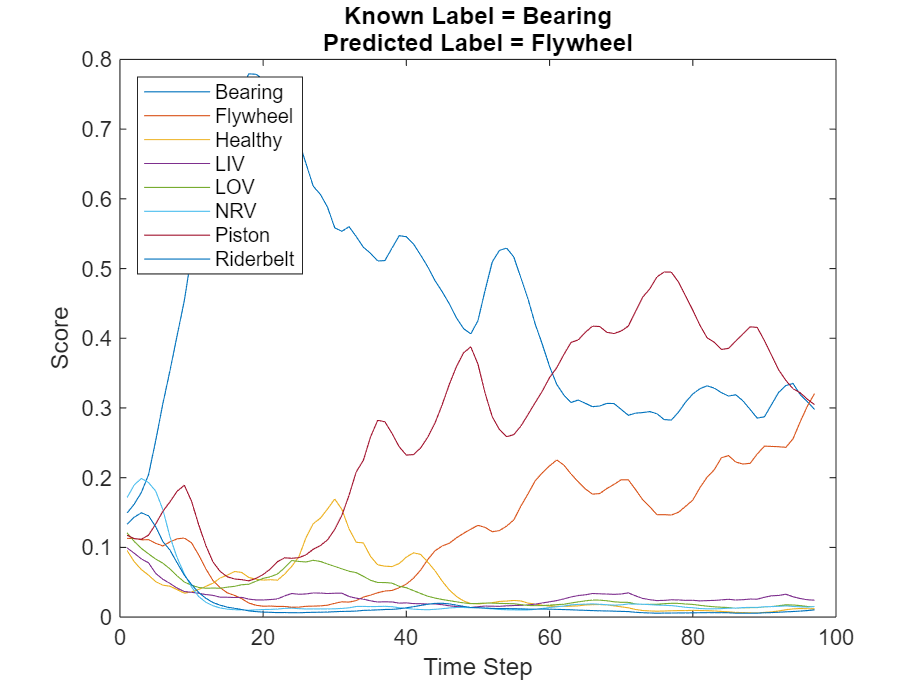

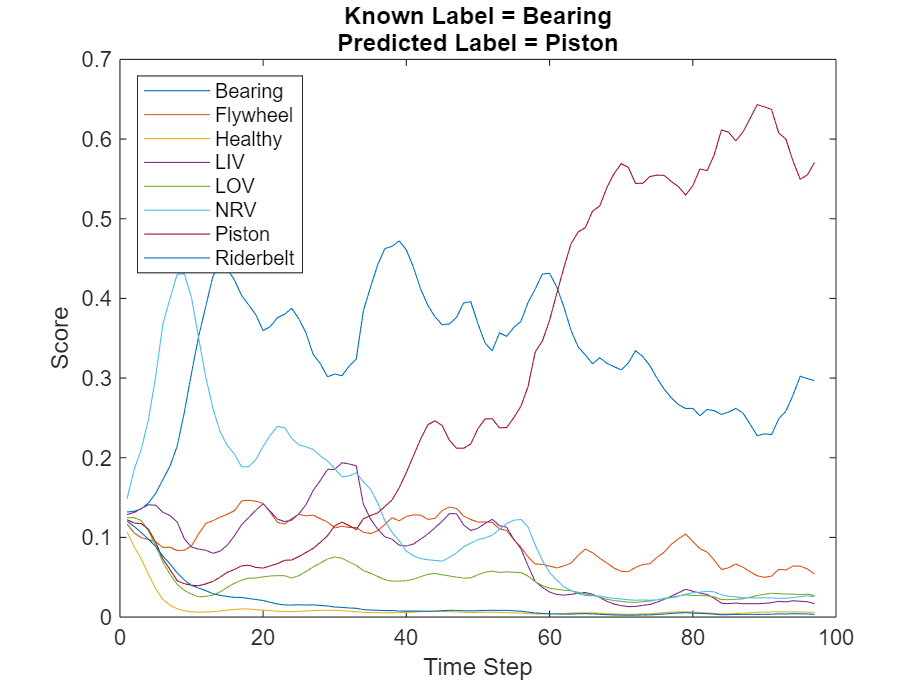

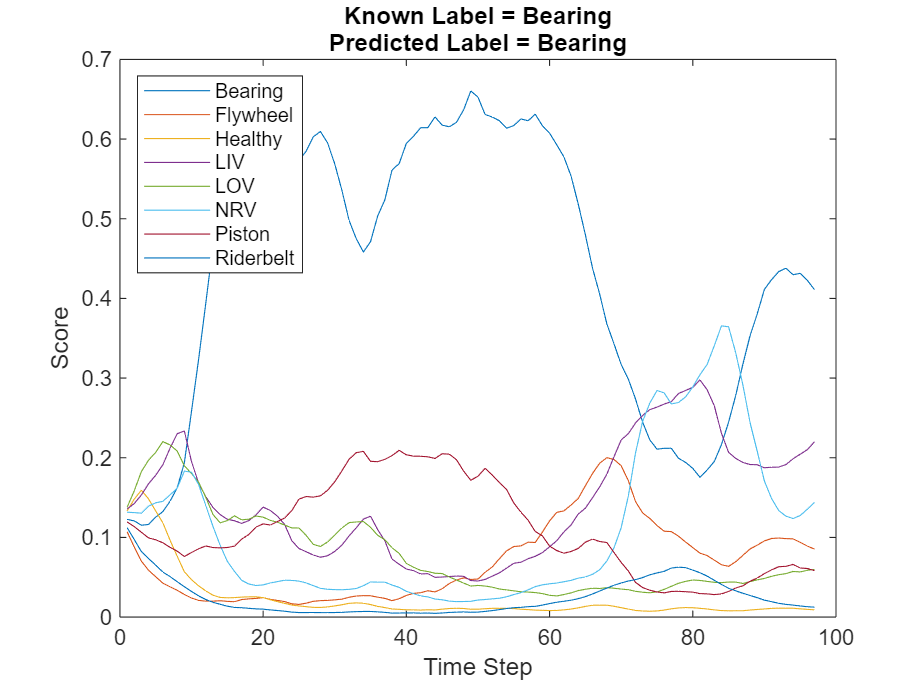

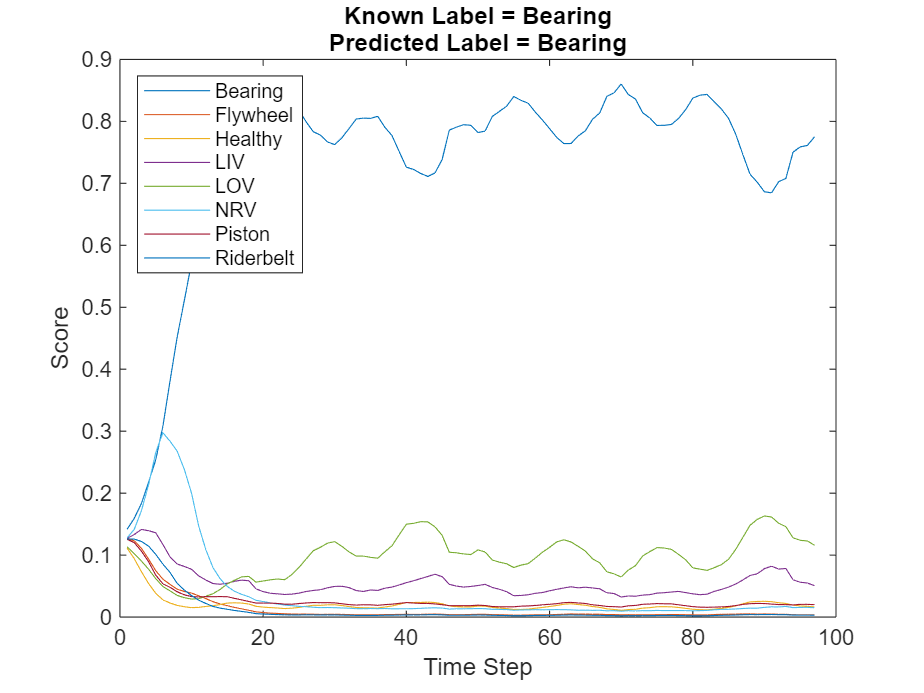

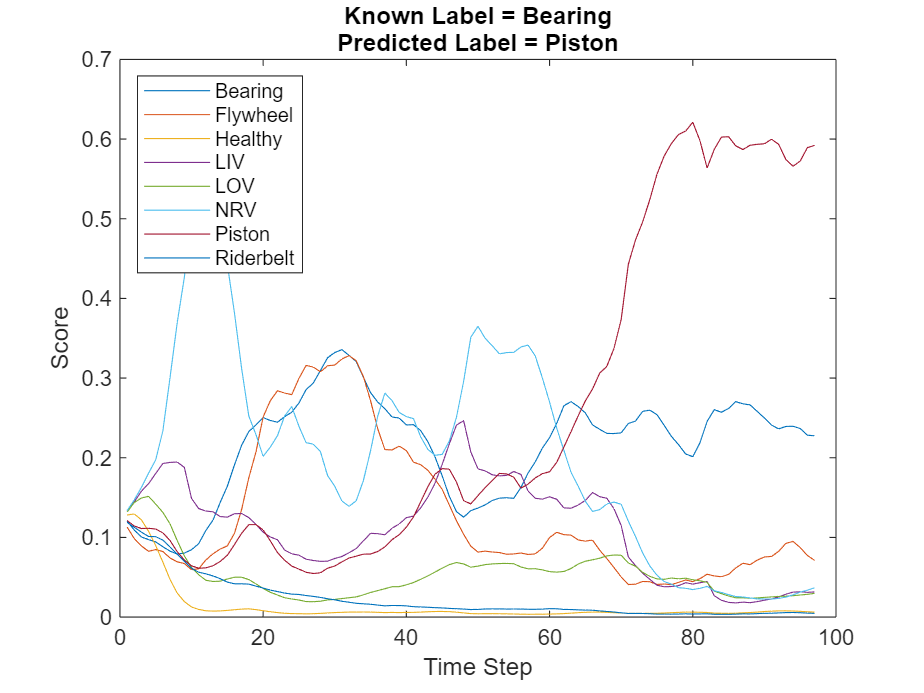

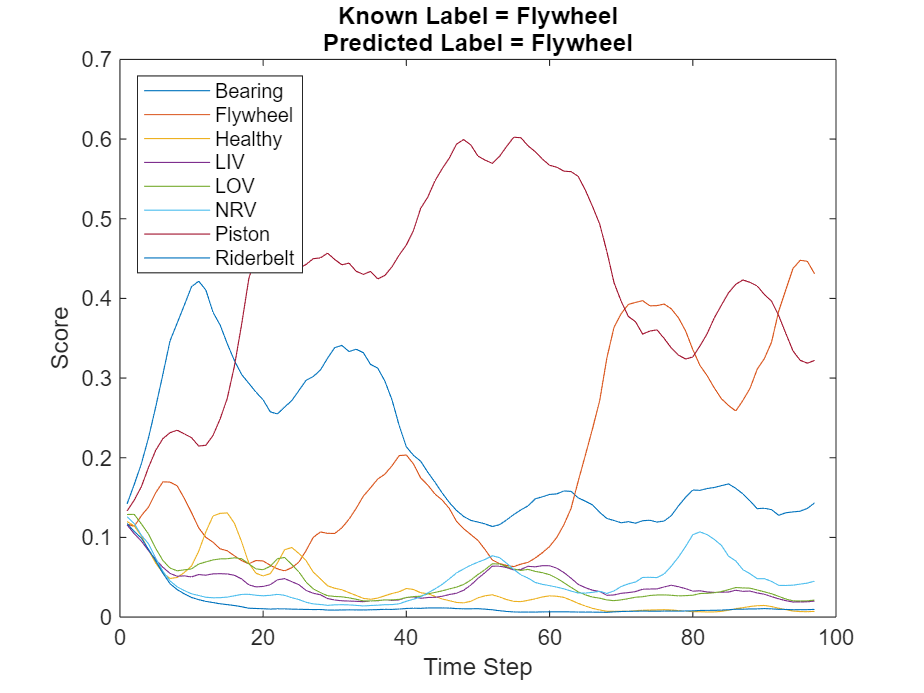

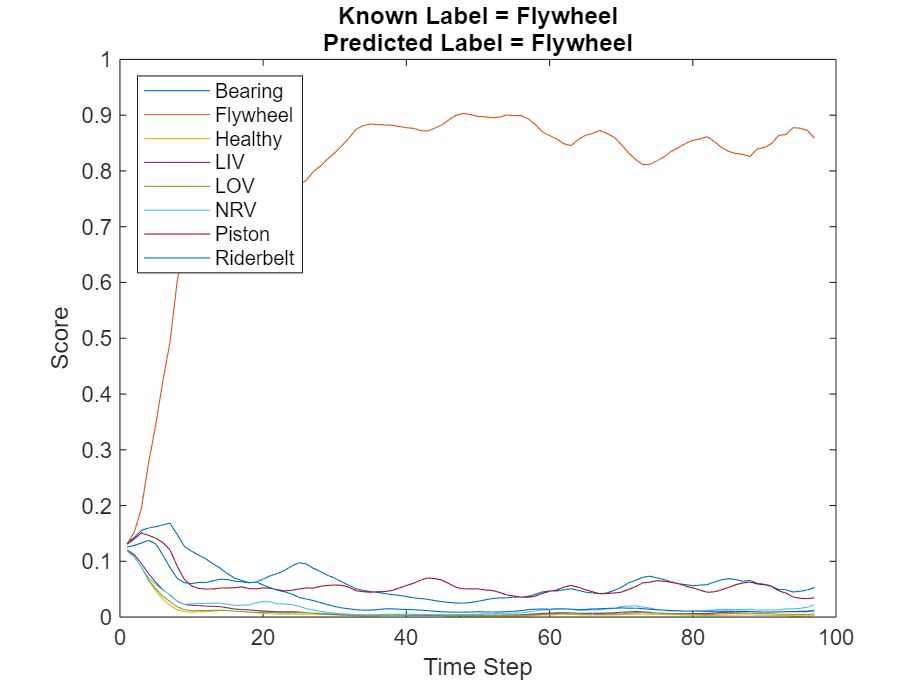

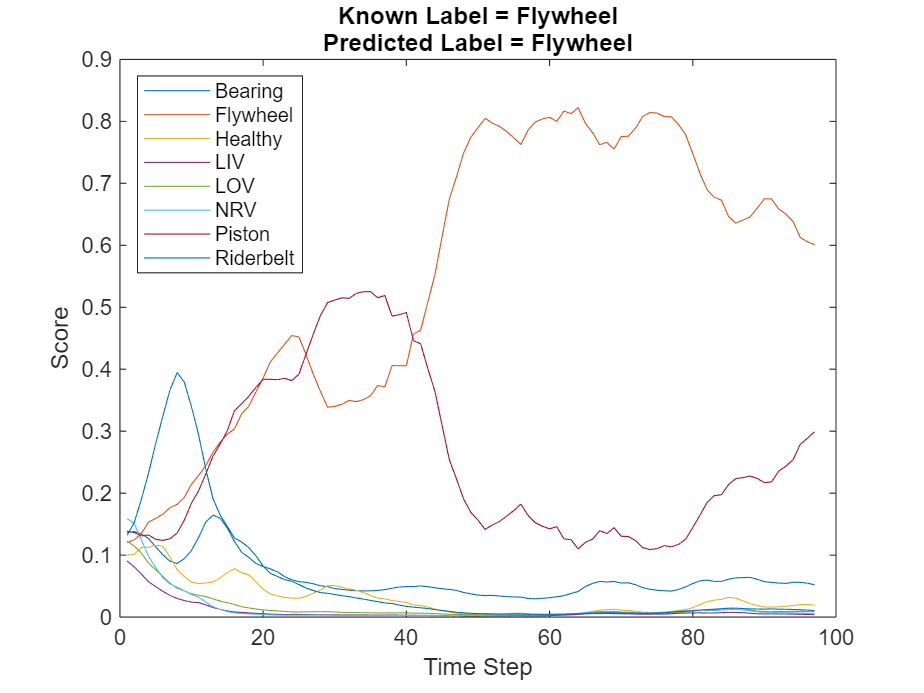

reset(adsValidation)

N = 10;
labels = categories(labelsValidation);
numLabels = numel(labels);

% Create a dsp.AsyncBuffer to read audio in a streaming fashion
audioSource = dsp.AsyncBuffer;

% Create a dsp.AsyncBuffer to accumulate scores
scoreBuffer = dsp.AsyncBuffer;

% Create a dsp.AsyncBuffer to record execution time.
timingBuffer = dsp.AsyncBuffer;

% Pre-allocate array to store results
streamingResults = categorical(zeros(N,1));

% Loop over files
for fileIdx = 1:N

    % Read one audio file and put it in the source buffer
    [data,dataInfo] = read(adsValidation);
    write(audioSource,data);

    % Inner loop over frames
    rs = true;
    while audioSource.NumUnreadSamples >= windowLength

        % Get a frame of audio data
        x = read(audioSource,windowLength);

        % Apply streaming classifier function
        tic
        score = recognizeAirCompressorFault(x,rs);
        write(timingBuffer,toc);

        % Store score for analysis
        write(scoreBuffer,extractdata(score)');

        rs = false;
    end
    reset(audioSource)

    % Store class result for that file
    scores = read(scoreBuffer);
    result = scores2label(scores(end,:),uniqueLabels,2);
    streamingResults(fileIdx) = result;

    % Plot scores to compare over time
    figure
    plot(scores) %#ok<*NASGU>
    legend(uniqueLabels,Location="northwest")
    xlabel("Time Step")
    ylabel("Score")
    title(["Known Label = " + string(labelsValidation(fileIdx)),"Predicted Label = " + string(streamingResults(fileIdx))])
end

Compare the test results for the streaming version of the classifier and the non-streaming.

testError = mean(validationResults(1:N) ~= streamingResults);
disp("Error between streaming classifier and non-streaming: " + testError*100 + " (%)")

Error between streaming classifier and non-streaming: 0 (%)


Analyze the execution time. The execution time when state is reset is often above the 32 ms budget. However, in a real, deployed system, that initialization time will only be incurred once. The execution time of the main loop is around 10 ms, which is well below the 32 ms budget for real-time performance.

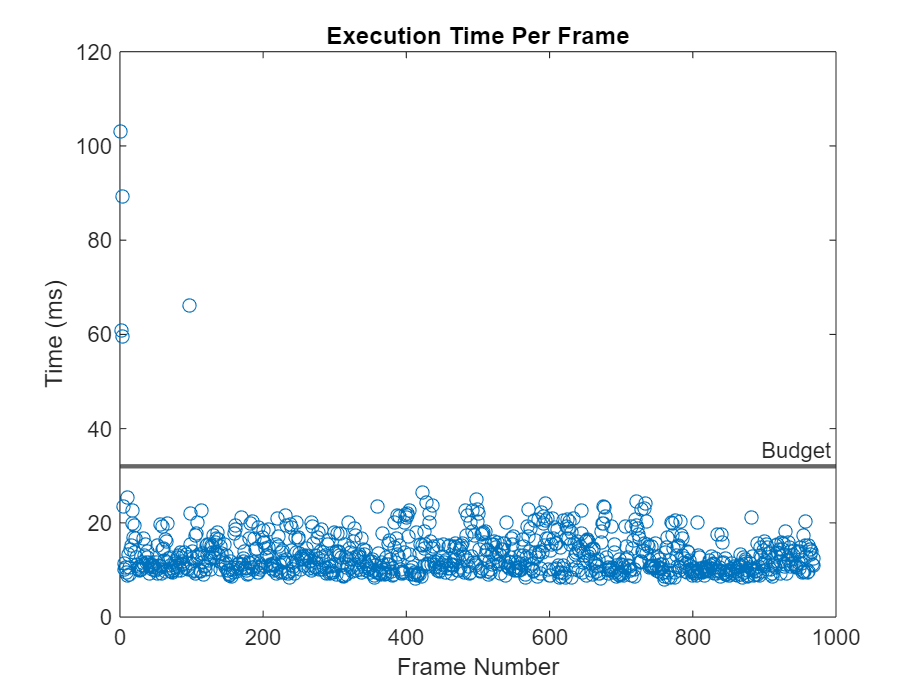

executionTime = read(timingBuffer)*1000;
budget = (windowLength/afe.SampleRate)*1000;
plot(executionTime(2:end),"o")
title("Execution Time Per Frame")
xlabel("Frame Number")
ylabel("Time (ms)")
yline(budget,"-","Budget",LineWidth=2)

# Supporting Functions

function [augData,augLabels] = mixup(data,labels,numMixesPerInstance)
augData = cell(numel(data)*numMixesPerInstance,1);
augLabels = repelem(labels,numMixesPerInstance);

kk = 1;
for ii = 1:numel(data)
    for jj = 1:numMixesPerInstance
        lambda = max(min((randn./10)+0.5,1),0);
        
        % Find all available data with different labels.
        availableData = find(labels~=labels(ii));

        % Randomly choose one of the available data with a different label.
        numAvailableData = numel(availableData);
        idx = randi([1,numAvailableData]);

        % Mix.
        augData{kk} = lambda*data{ii} + (1-lambda)*data{availableData(idx)};

        % Specify the label as randomly set by lambda.
        if lambda < rand
            augLabels(kk) = labels(availableData(idx));
        else
            augLabels(kk) = labels(ii);
        end
        kk = kk + 1;
    end
end

end

# References

[1] Verma, Nishchal K., et al. "Intelligent Condition Based Monitoring Using Acoustic Signals for Air Compressors." IEEE Transactions on Reliability, vol. 65, no. 1, Mar. 2016, pp. 291–309. DOI.org (Crossref), doi:10.1109/TR.2015.2459684.

[2] Huszar, Ferenc. "Mixup: Data-Dependent Data Augmentation." InFERENCe. November 03, 2017. Accessed January 15, 2019. [https://www.inference.vc/mixup-data-dependent-data-augmentation/](https://www.inference.vc/mixup-data-dependent-data-augmentation/).

*Copyright 2021-2023 The MathWorks, Inc.*